#### General parameters 

These are the same 'options' used for the filtering and segmentation

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

#### Systolic Peaks, Diastolic Peaks and Waveform Feet

See M. Elgendi "On the Analysis of Fingertip Photoplethysmogram Signals" p. 6

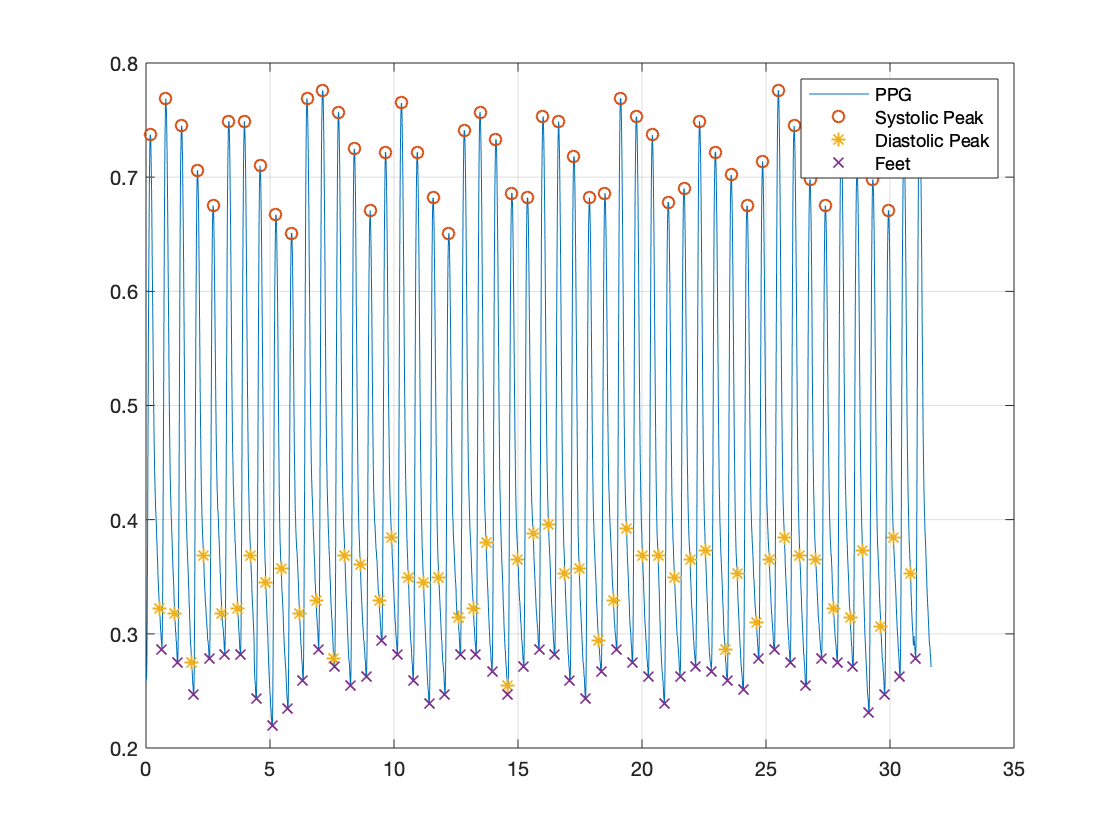

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3739816_0022-0012.txt");
[sys, dias, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sys,1), data(sys,3), 'o', 'LineWidth',1);
scatter(data(dias,1), data(dias,3), '*', 'LineWidth',1)
scatter(data(feet,1), data(feet,3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

#### Systolic and Diastolic Peak Amplitudes

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);
disp('Systolic Points')
mean_amp = mean(data(systolic_pts,3))
dev_amp = std(data(systolic_pts,3))

Systolic Points


max_amp = max(data(systolic_pts,3))

mean_amp = 2.6740

min_amp = min(data(systolic_pts,3))

dev_amp = 0.4107

max_amp = 3.3710

disp('Diastolic Pts')

min_amp = 1.5220

mean_amp = mean(data(diastolic_pts,3))
dev_amp = std(data(diastolic_pts,3))

Diastolic Pts


max_amp = max(data(diastolic_pts,3))

mean_amp = 1.6999

min_amp = min(data(diastolic_pts,3))

dev_amp = 0.5306

max_amp = 2.7100

min_amp = 0.7050

#### Heart Rate extraction from PPG

First the ppg foot waveform locations are extracted

Then these are used to find the HR (mean, max, most recent)

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0005-0015.txt");

[~,~,ppg_feet] = findSystolicPeaks(data(:,3));
[hr_avg, hr_max, hr_most_rec] = heartRateFromPPG(ppg_feet, opts.samp_freq)
clf
plot(data(:,1), data(:,3))
hold on

hr_avg = 75.7523

hr_max = 81.5217

hr_most_rec = 73.5294

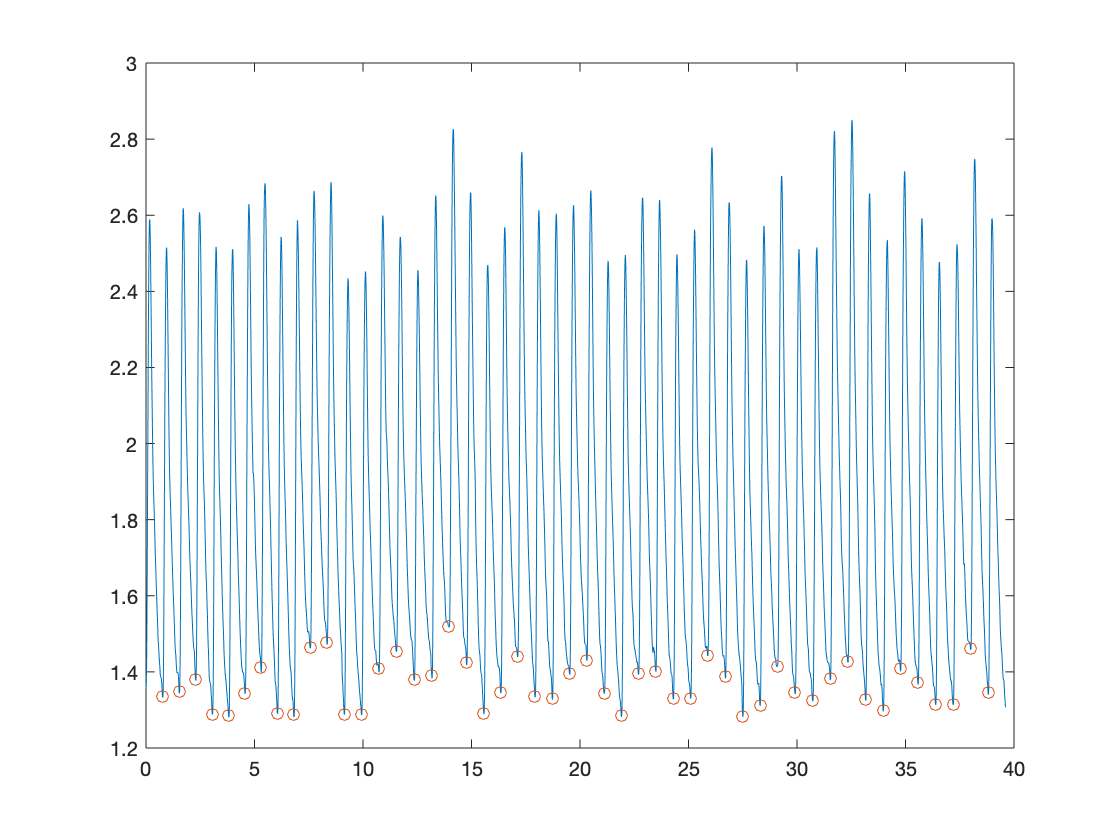

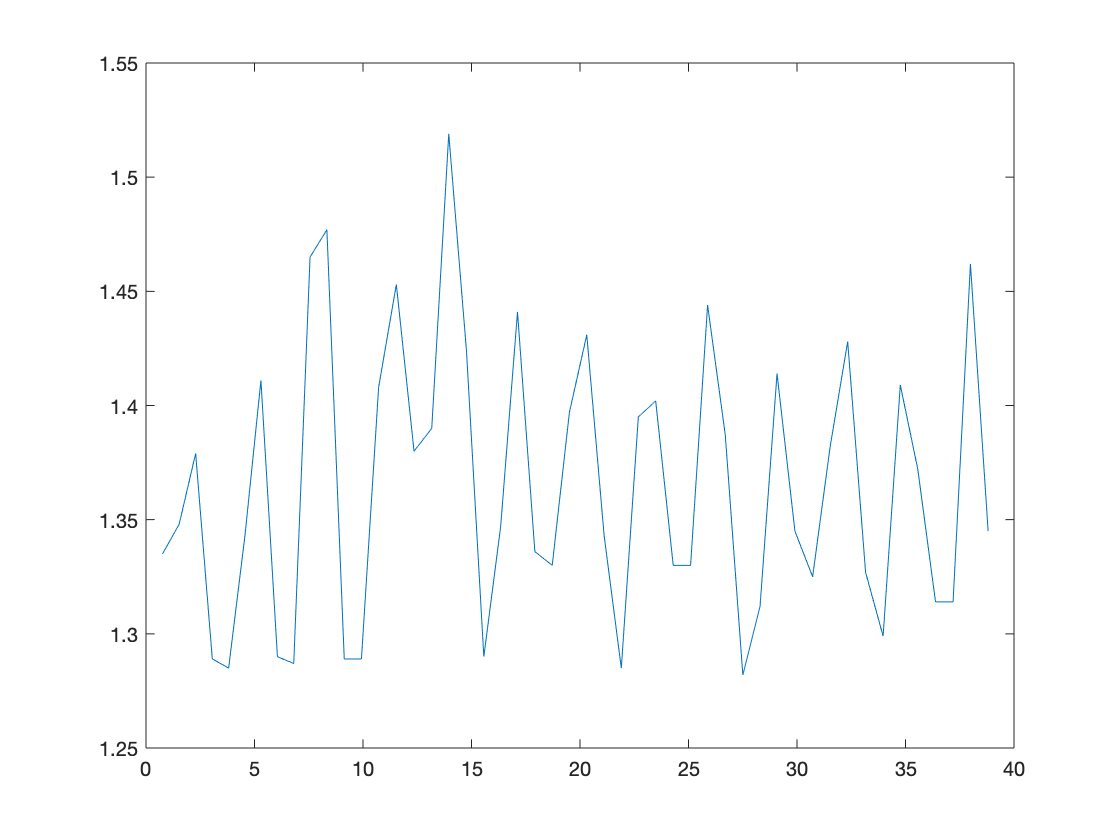

scatter(data(ppg_feet,1), data(ppg_feet,3))
clf
plot(data(ppg_feet,1), data(ppg_feet,3))


#### PPG Time and Area Intervals

Time to systolic peak, time to diastolic peak

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

sortedPeaks = sortPPGPeaks(systolic_pts, diastolic_pts, feet);

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sortedPeaks(:,2),1), data(sortedPeaks(:,2),3), 'o', 'LineWidth',1);
scatter(data(sortedPeaks(:,3),1), data(sortedPeaks(:,3),3), '*', 'LineWidth',1)
scatter(data(sortedPeaks(:,1),1), data(sortedPeaks(:,1),3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

#### Respiratory rate from PPG

See P.S.Addison et al. [https://sci-hub.se/10.1007/s10877-011-9332-y](https://sci-hub.se/10.1007/s10877-011-9332-y)

Typical freq range of respiration is [2.97;28.02] breaths/min <=> [0.05;0.47] Hz. A heart rate of [45;220] bpm <=> [0.75; 3.67] Hz ie. signals should be able to be separated

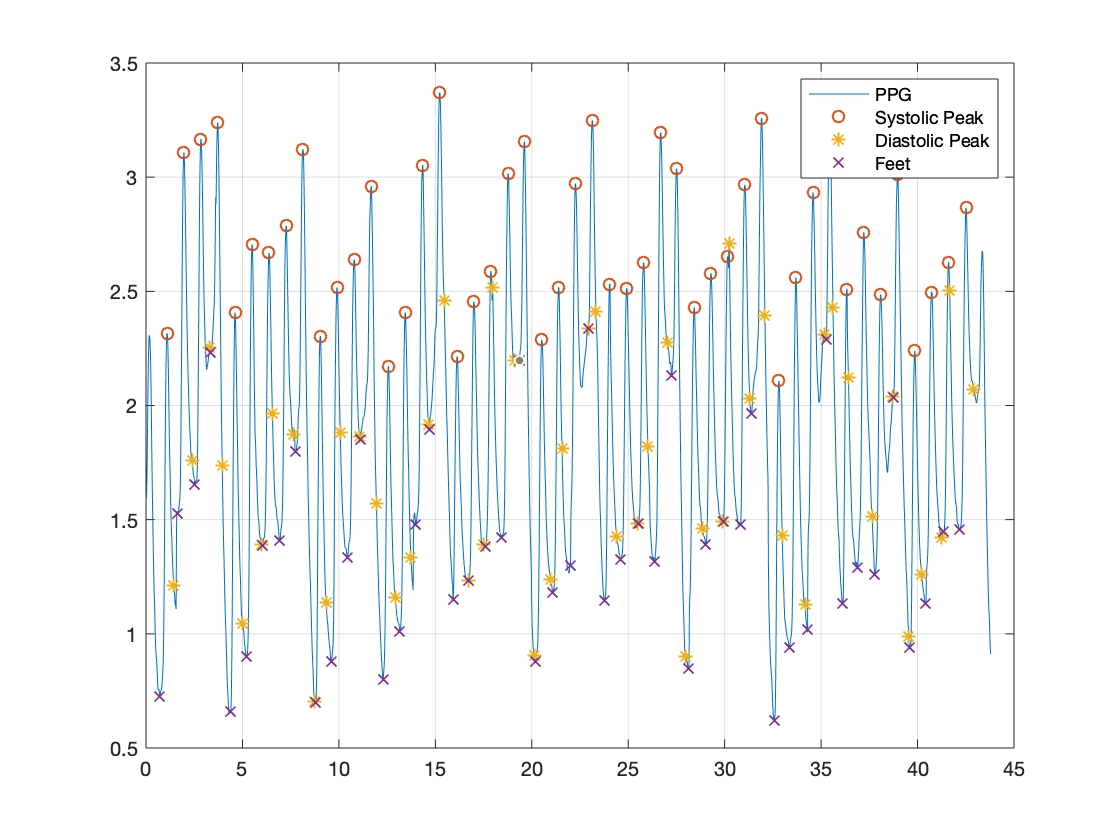

addpath('./TimeFeatures')

data = importdata("../physionet.org/segmented_data/3000393_0015-0009.txt");


resp_rate = getRespiratoryRateFreq(data(:,1), data(:,3))

clf
plot(data(:,1), data(:,3))
hold on
plot(data(:,1), 0.2.*sin(2*pi*resp_rate.*data(:,1))+mean(data(:,3)), 'Color', 'black')

resp_rate = 0.2624

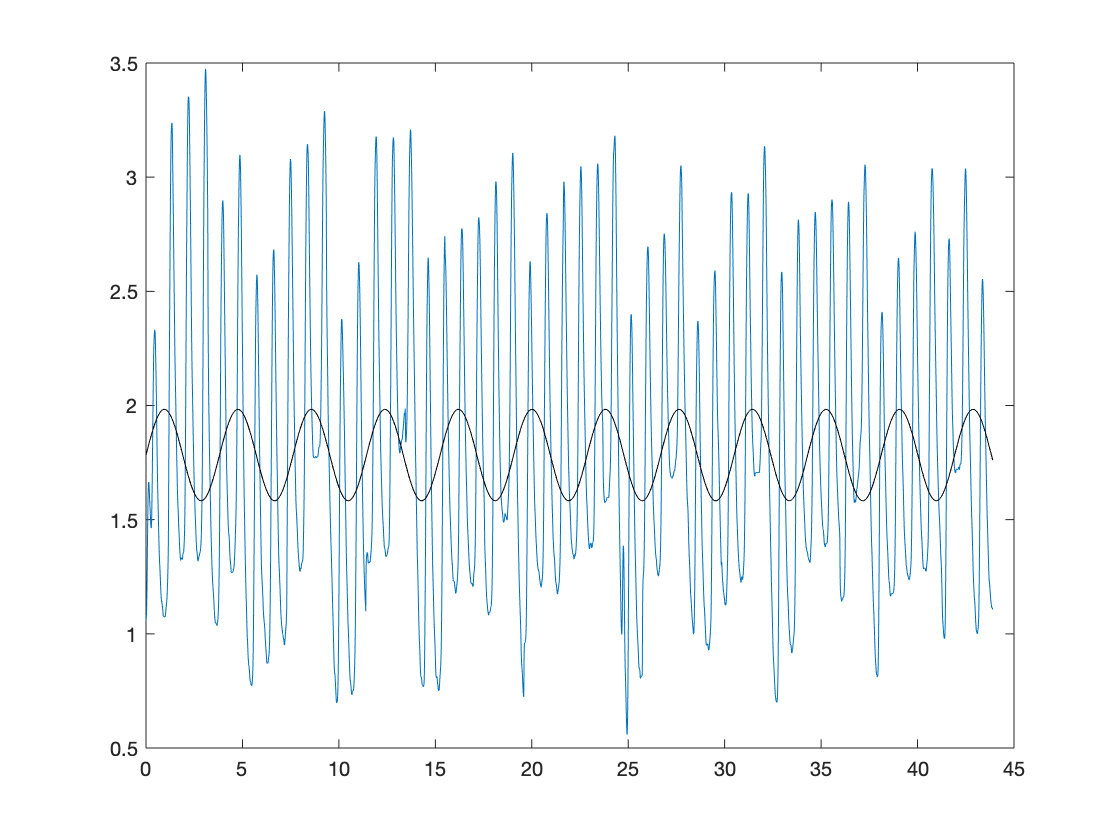


function [freqVector, freqSpectrum] = singlesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));

Systolic Points


mean_amp = 2.6857

dev_amp = 0.3486

max_amp = 3.3540

min_amp = 2.0730

Diastolic Pts


mean_amp = 1.3591

dev_amp = 0.4228

max_amp = 2.2050

min_amp = 0.6460

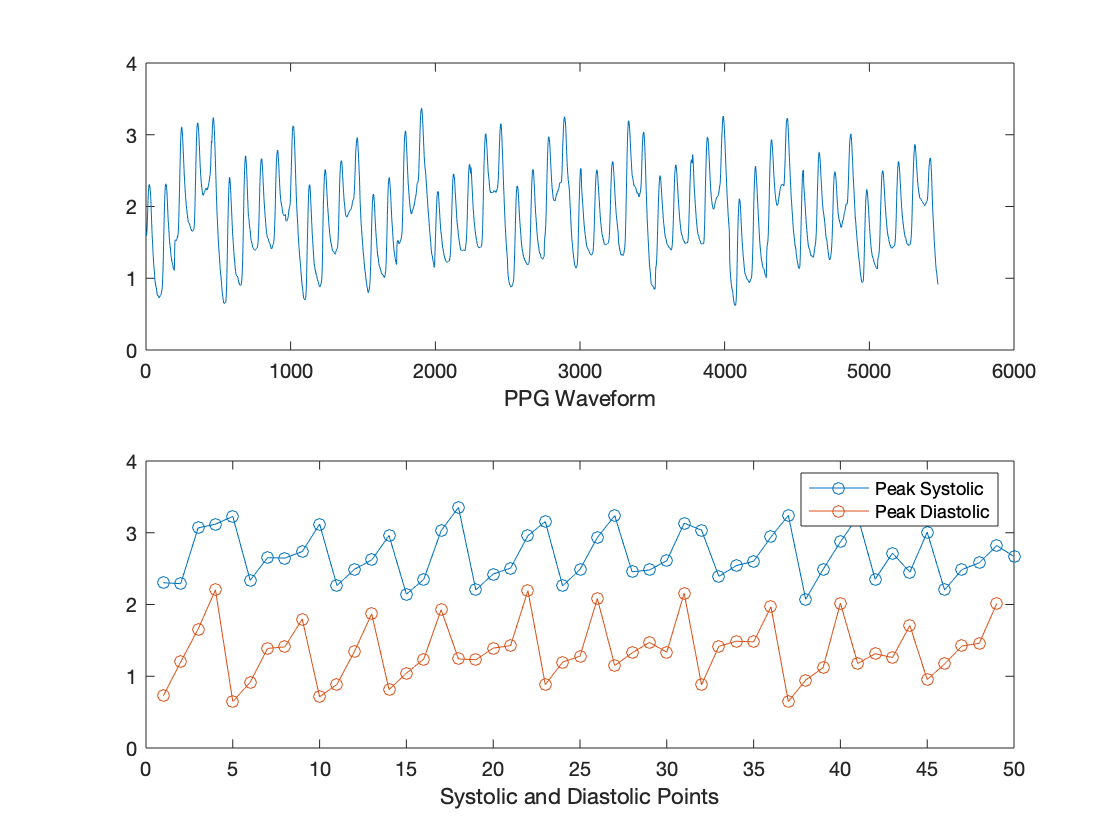

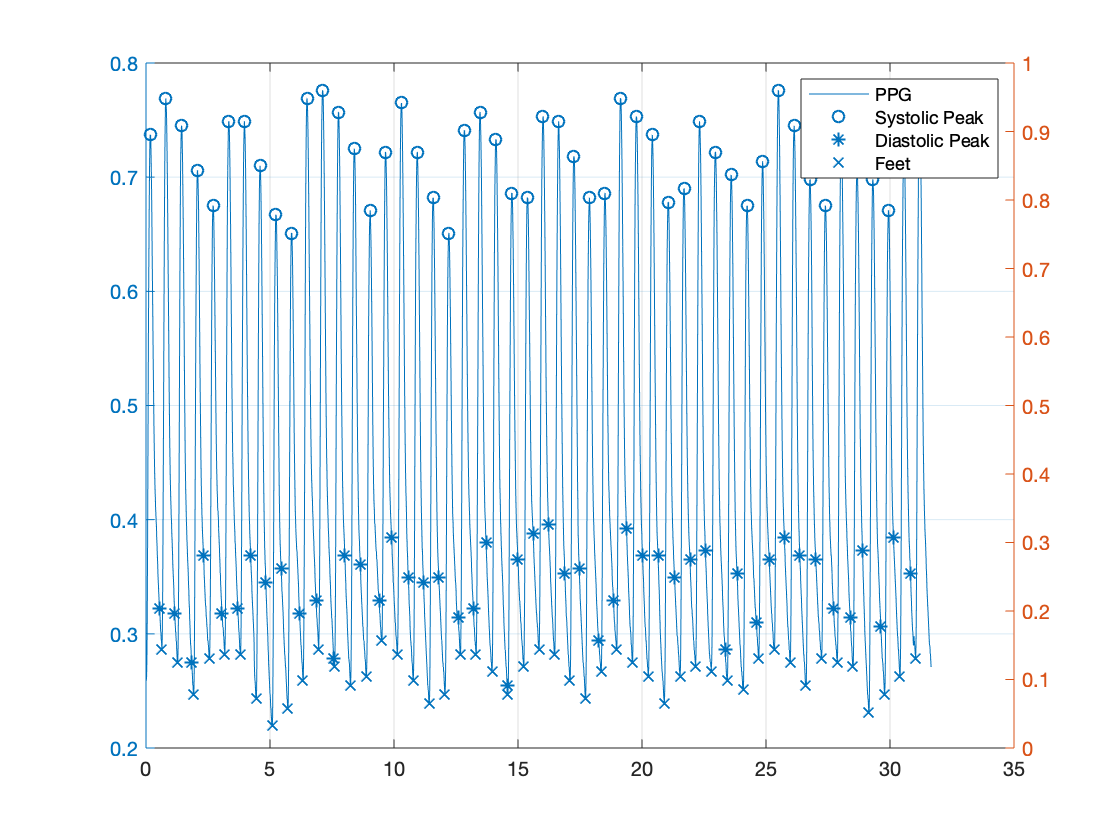

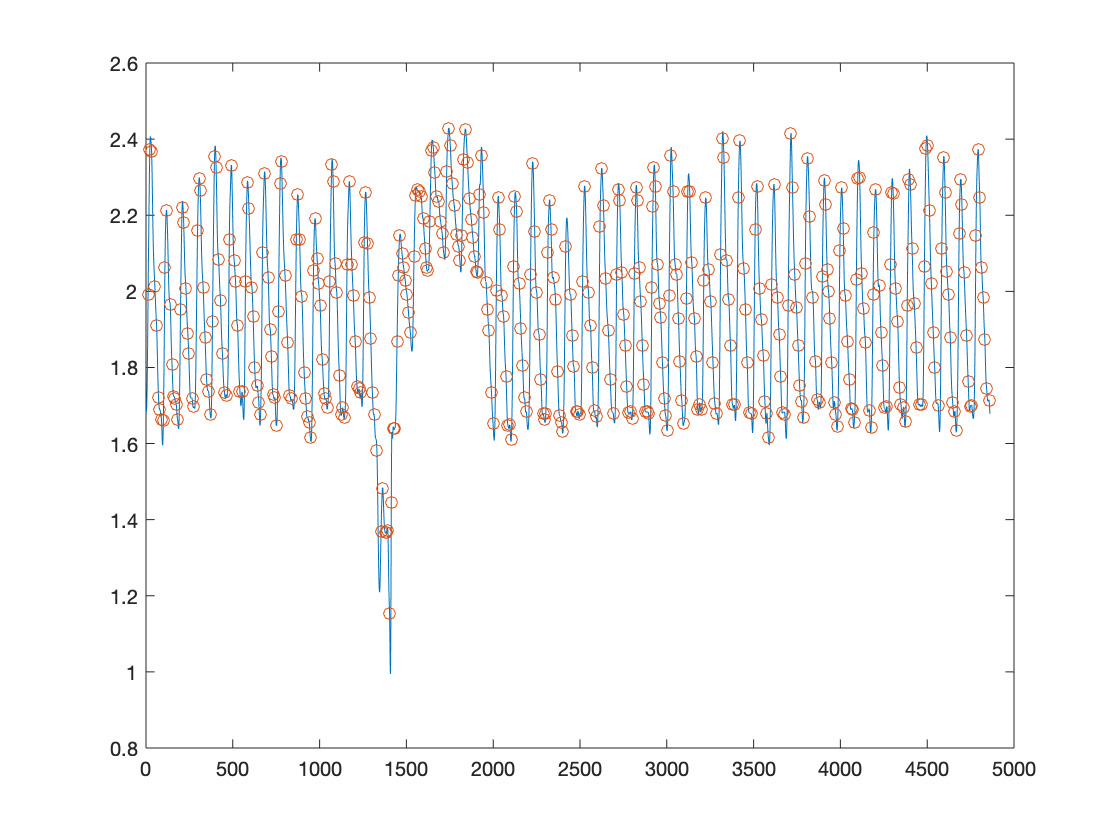

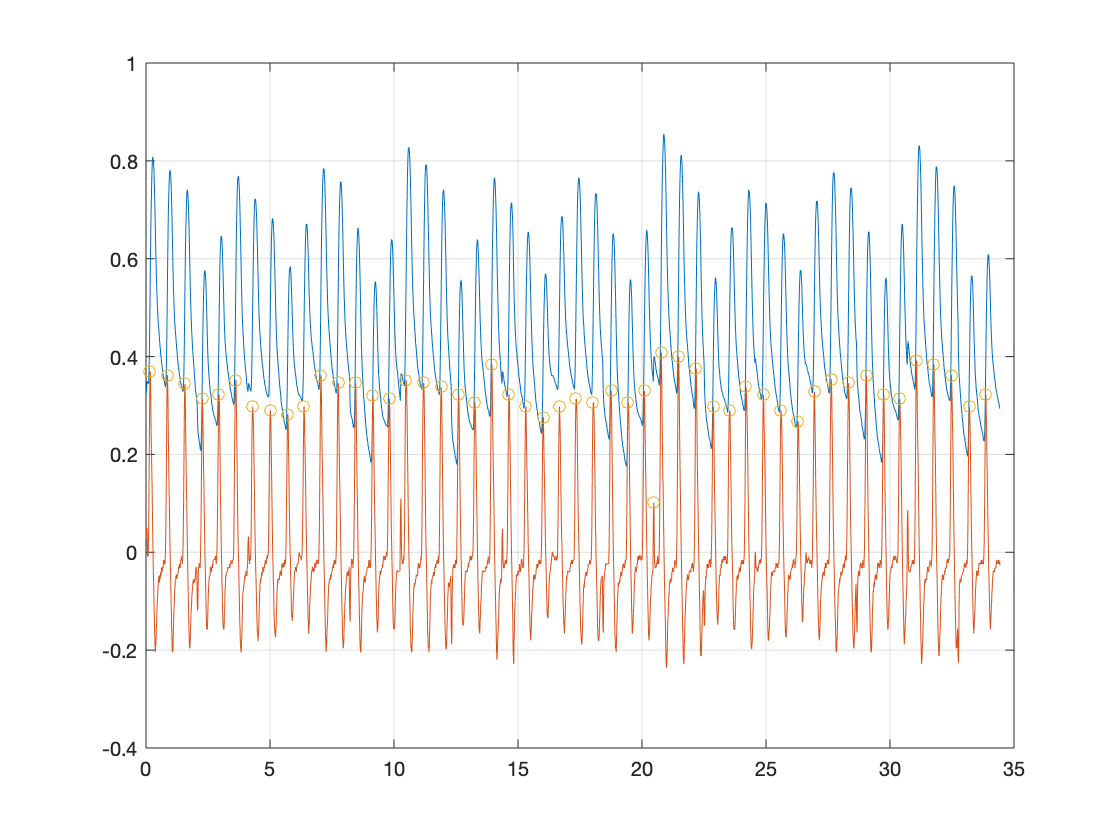

   df = 1/dT;

   %freqVector = (-n/2:(n/2-1))* (df/n);
   freqVector = (0:(n/2 -1)) * (df/n);
   freqSpectrum = fft(timeSignal)/df;
   freqSpectrum(floor(n/2)+1 : end) = [];
   freqSpectrum(2:end) = freqSpectrum(2:end) * 2;
end

function [freqVector, freqSpectrum] = doublesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));
   df = 1/dT;
   freqVector = (-n/2:(n/2-1))* (df/n);
   freqSpectrum = fftshift(fft(timeSignal))/df;
end


